Textfile = load("STM32Output.txt")

Textfile =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


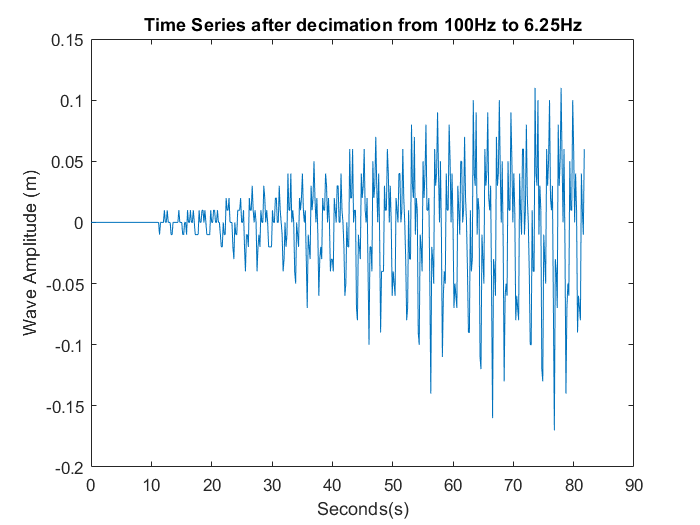

writematrix(Textfile, "STM32Output.csv");
timeSeriesData = readtable("STM32Output.csv");


N =  1024 - 1; 
timeSeriesData = timeSeriesData{:, 1}; %data is symmetric, *2 to account for contribution of other half 
fs = 6.25;
time = 1/fs*(0:(N));

plot(time(1:512), timeSeriesData(1:512)); %only plotting the real side of the dataset 
title("Time Series after decimation from 100Hz to 6.25Hz");
xlabel("Seconds(s)");
ylabel("Wave Amplitude (m)");